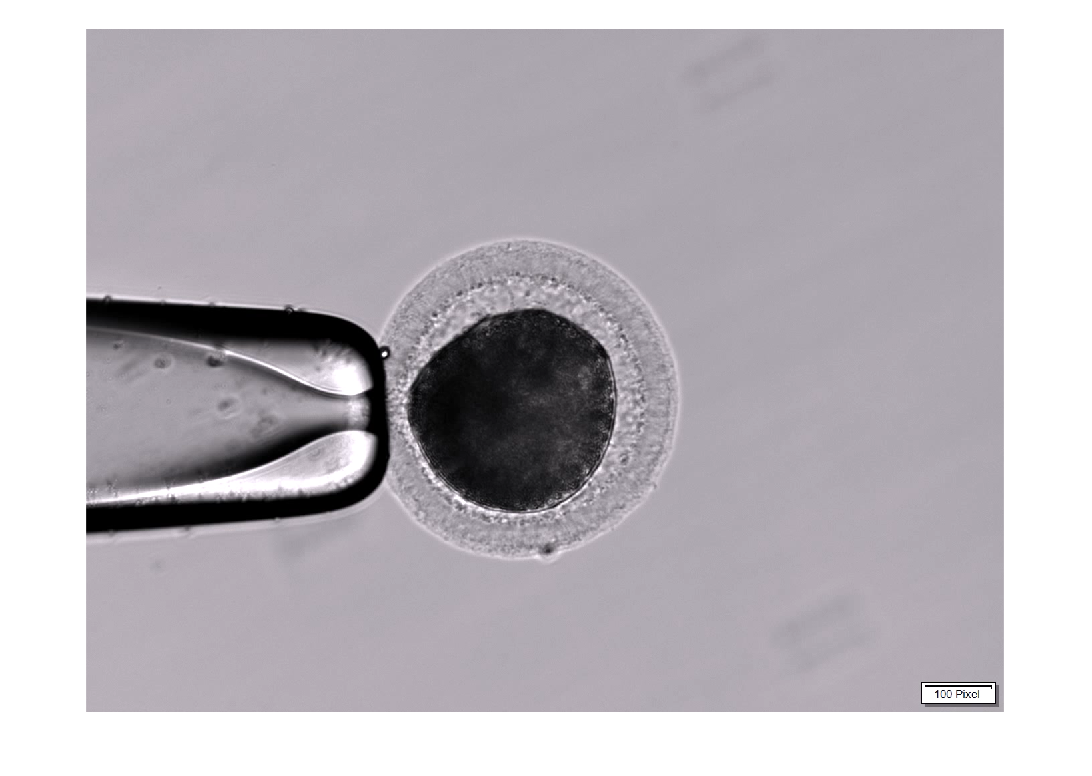

clear; close all; clc
Name ='2951Film_322_GV-1.5M-EG.tif';
imread (Name);
RGB=imread(Name);
imshow(RGB);

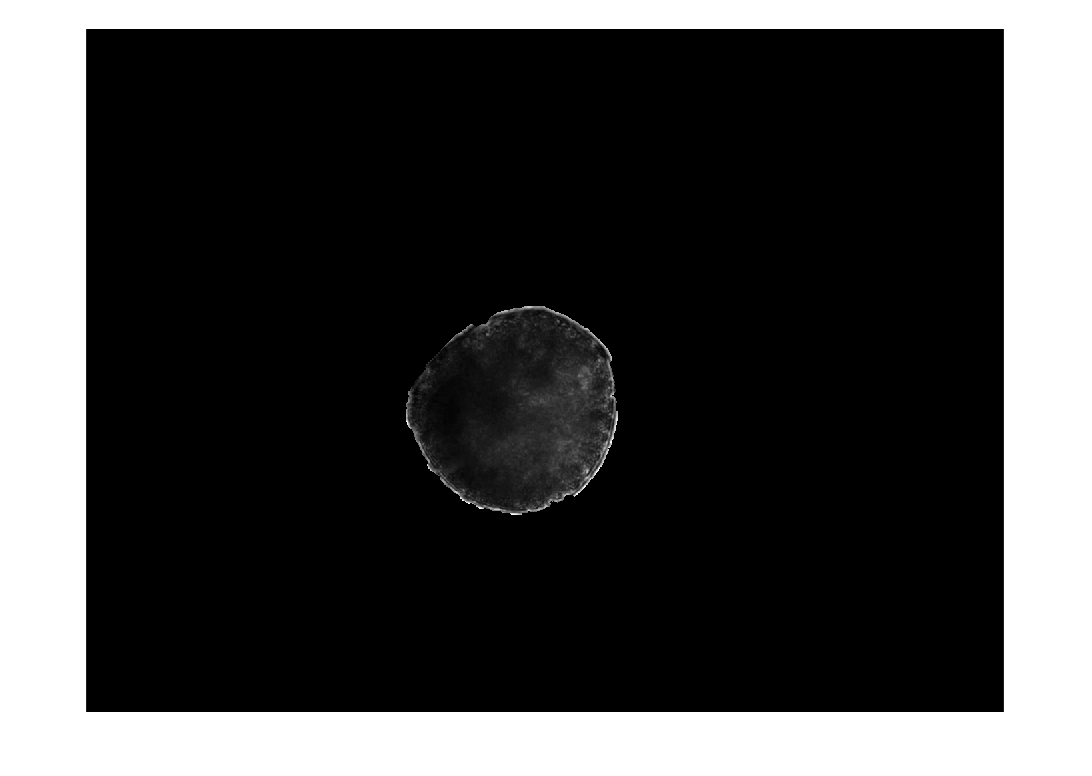

[BW,maskedImage] = segmentImage_322_EG(RGB);
I=rgb2gray(maskedImage);
imshow(I)

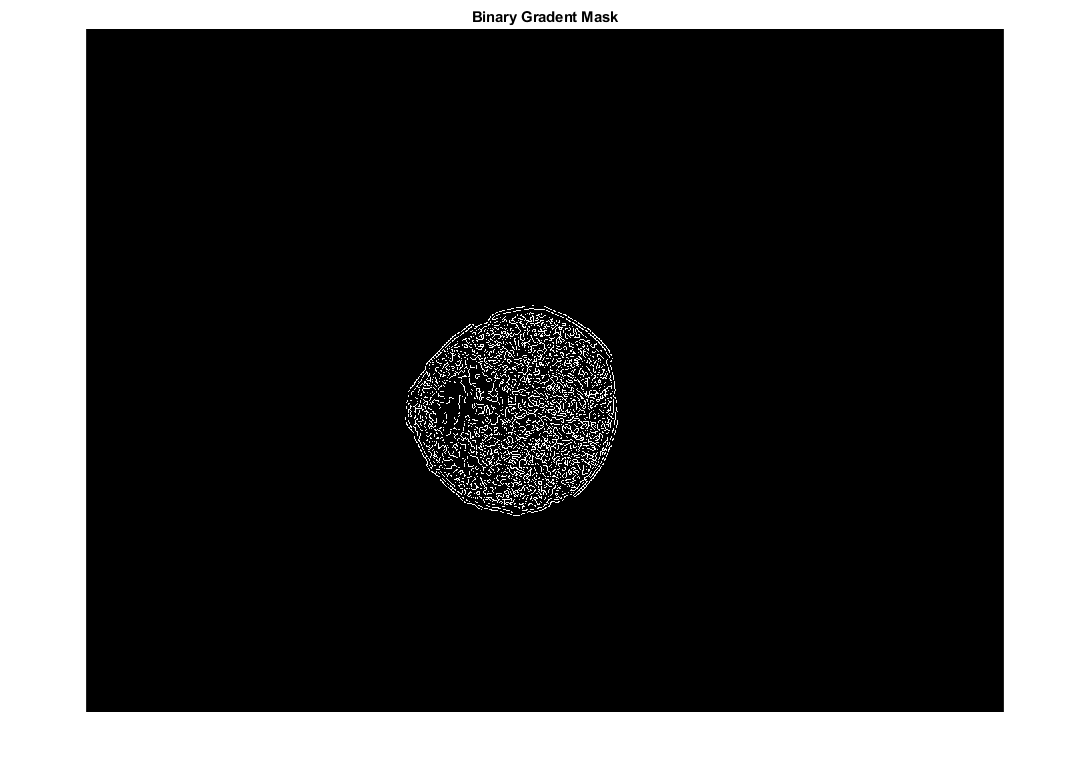

[~,threshold]=edge(I,'Canny');
fudgefactor =1;
BWs=edge(I,'Canny',threshold*fudgefactor);
imshow(BWs)
title('Binary Gradent Mask')

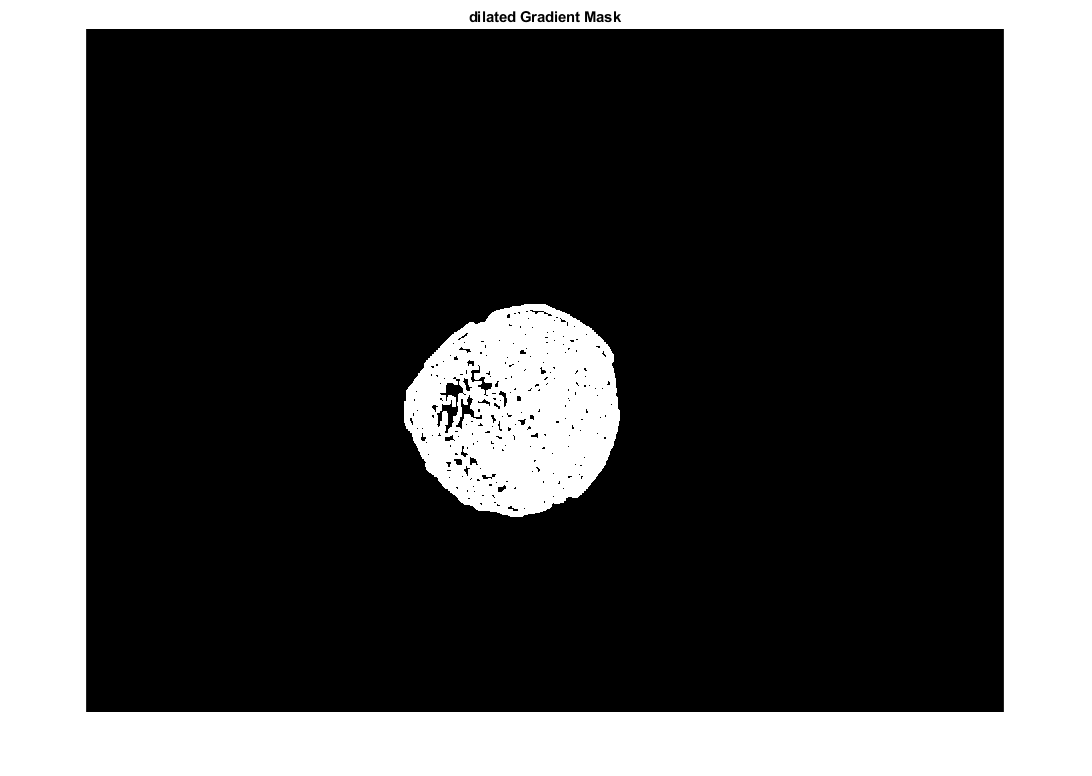

se90=strel('line',4,90);
se0=strel('line',4,0);
BWsdil=imdilate (BWs,[se90 se0]);
imshow(BWsdil)
title ('dilated Gradient Mask');

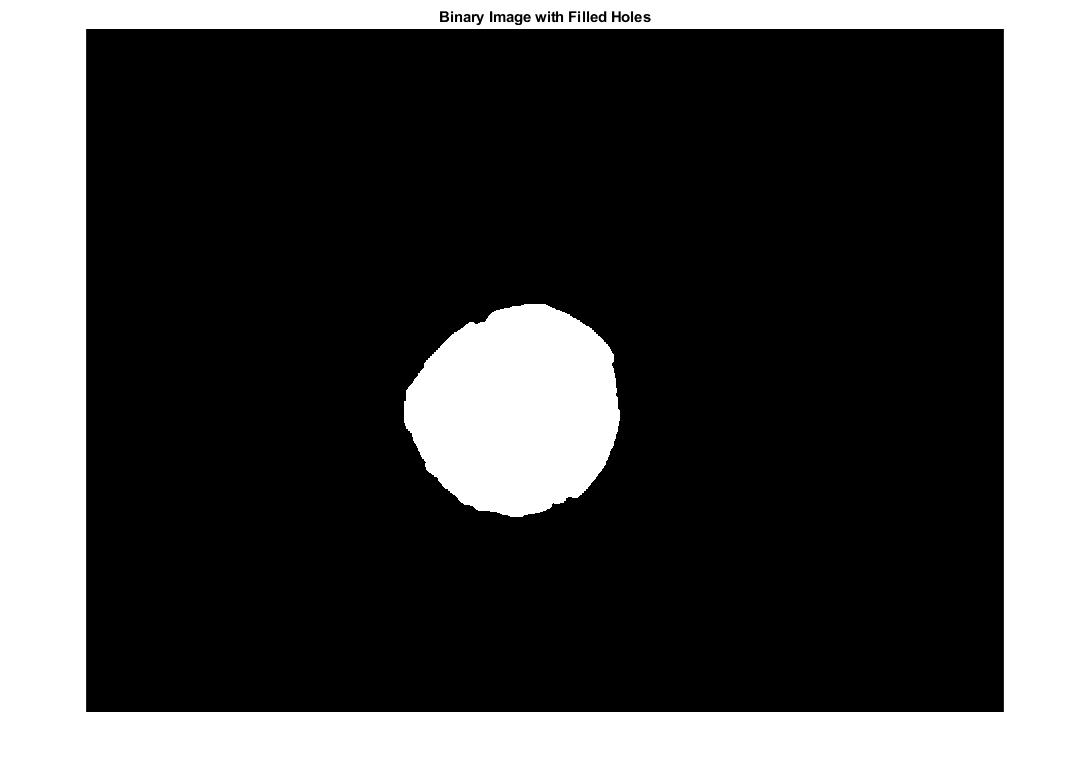

BWdfill=imfill(BWsdil,"holes");
imshow(BWdfill)
title('Binary Image with Filled Holes');

seD=strel('octagon',3);
BWfinal=imerode(BWdfill,seD);
imshow(BWfinal)
title('BWfinal')
stats = regionprops('table',BWfinal,'Centroid',"MajoraxisLength",'MinoraxisLength');
centers= stats.Centroid;
diameters= mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii=diameters/2;
hold on
viscircles(centers,radii);
disp(max([diameters radii]))

  309.8585



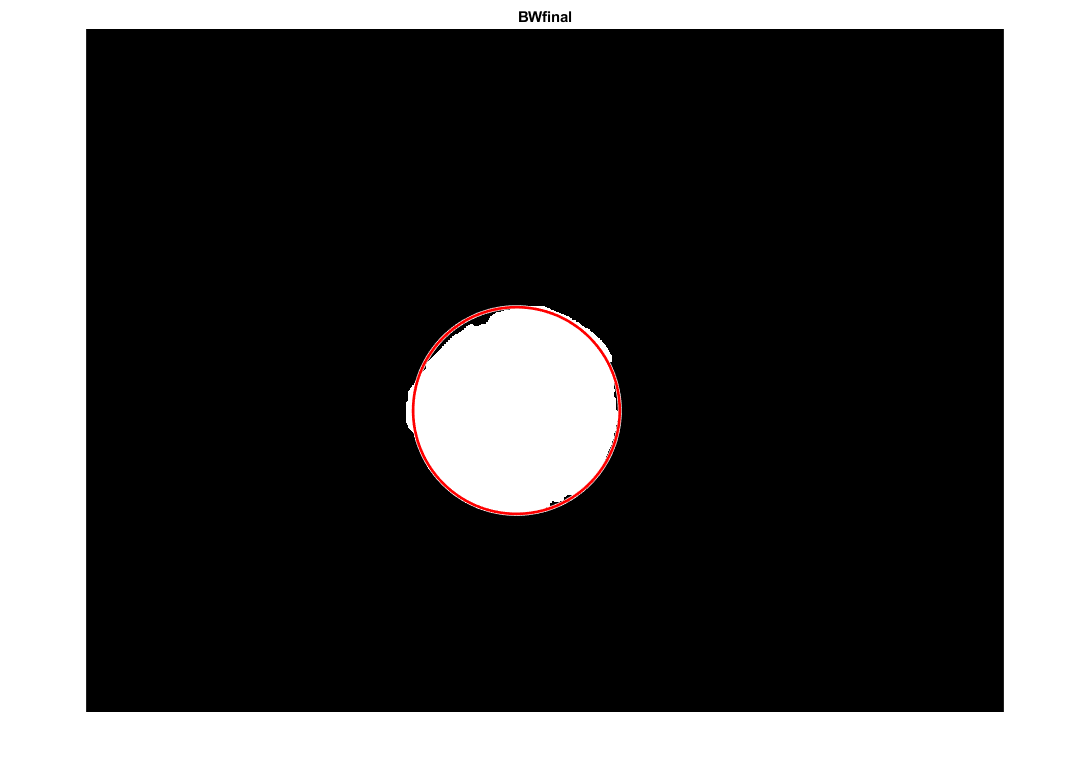

hold off

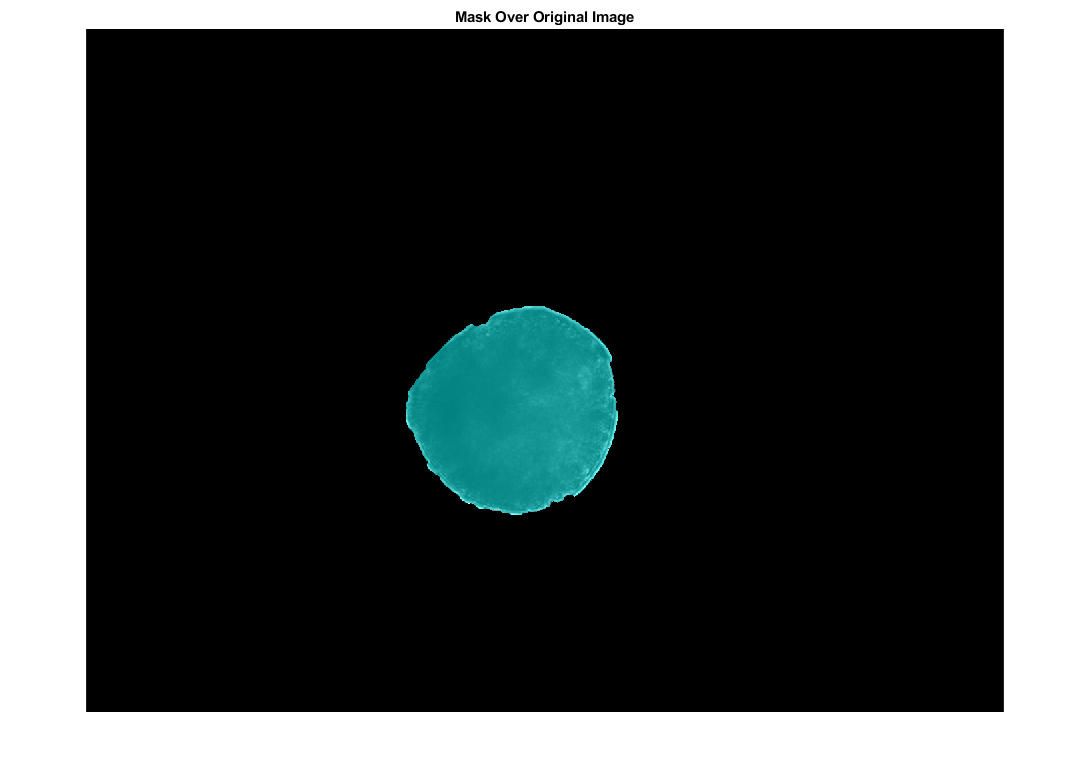

imshow(labeloverlay(I,BWfinal))
title('Mask Over Original Image')